# High Voltage Battery - Main Script

mdl = "BatteryHV_harness_model";
load_system(mdl)

% Load model parameters.
BatteryHV_harness_setup

% Select battery model.
BatteryHV_useRefsub_Basic

Model: BatteryHV_harness_model
Setting up referenced subsystem: BatteryHV_refsub_Basic



% Setup simulation case.
BatteryHV_selectSimulationCase_Random

Setting up simulation...
Simulation case: Random input
Setting simulation stop time to 1082 sec.
Setting block parameters for input blocks...
Setting initial conditions...
initial.hvBattery_SOC_pct = 60
initial.hvBattery_Charge_Ahr = 6.8571
initial.hvBattery_Temperature_K = 293.15


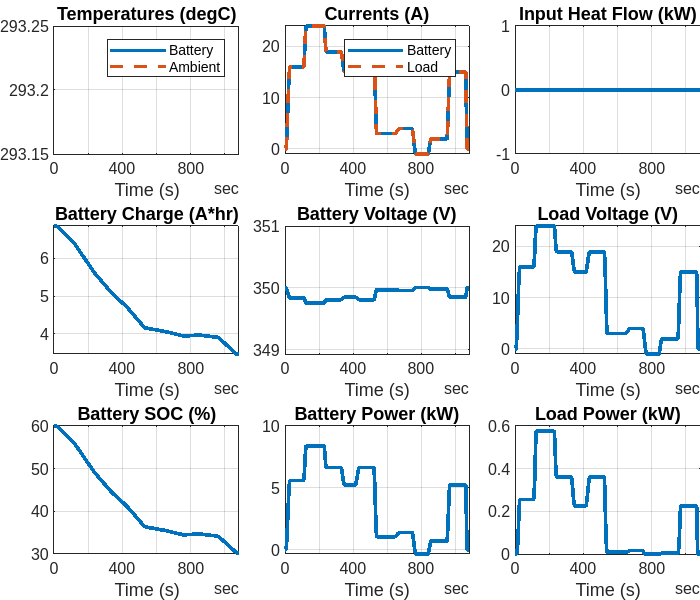


% Run simulation.
simOut = sim(mdl);

% Collect logged signals and visualize.
% The basic version of the battery block does not simulate battery temperature.
logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals)

*Copyright 2020-2023 The Mathworks, Inc.*